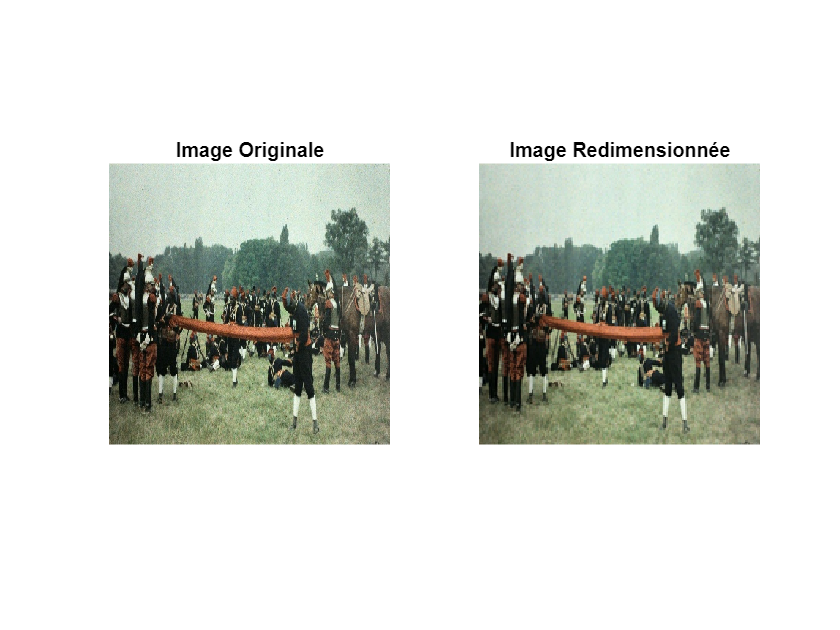

% Redimensionner l'image haute résolution

im = imread("tirailleurs2.jpg");
im_resized = imresize(im, 0.5, 'Method', 'lanczos3');
cd ./SR
figure
subplot(1,2,1);
imshow(im);
title("Image Originale");
subplot(1,2,2);
imshow(im_resized);
title("Image Redimensionnée");

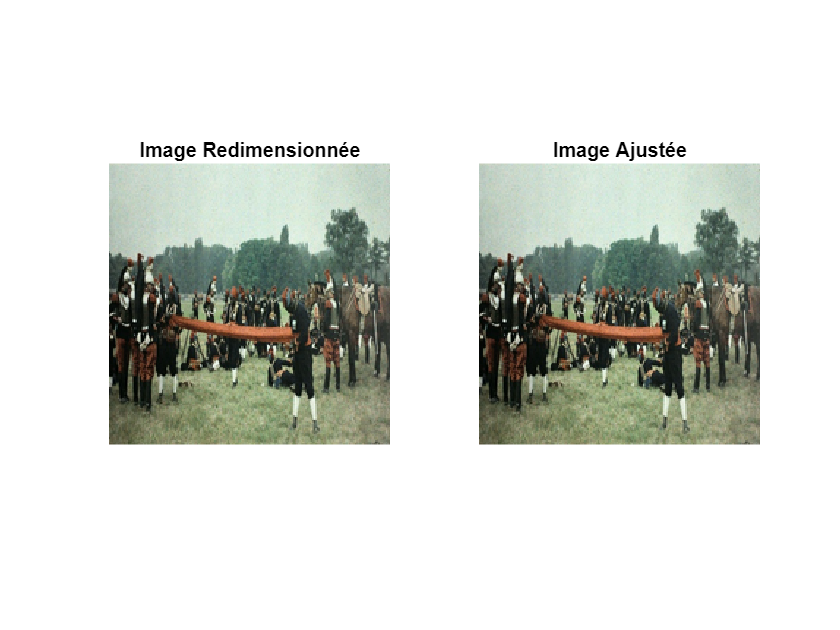

% Ajuster la taille de l'image
scale = 2;
szGT = size(im_resized);
newSz = [int32((szGT(1:2)-(scale-1))/scale) * scale, 3];
rect = images.spatialref.Rectangle([1 newSz(2)], [1 newSz(1)]);
im_cropped = imcrop(im_resized, rect);

figure
subplot(1,2,1);
imshow(im_resized);
title("Image Redimensionnée");
subplot(1,2,2);
imshow(im_cropped);
title("Image Ajustée");

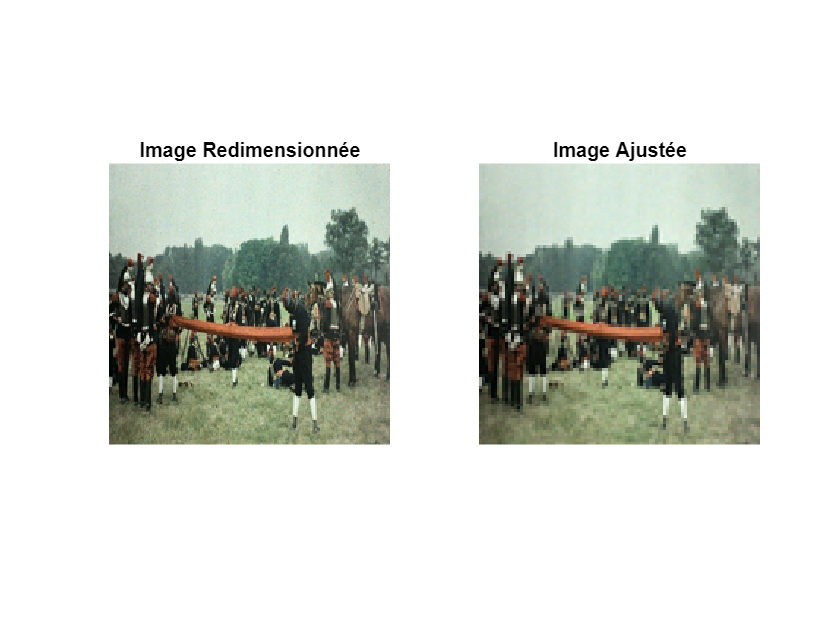

% Récupèrer les canaux de l'image individuellement
im_recropped = imresize(im_cropped, 1.0/2, 'lanczos3');

figure
subplot(1,2,1);
imshow(im_cropped);
title("Image Redimensionnée");
subplot(1,2,2);
imshow(im_recropped);
title("Image Ajustée");

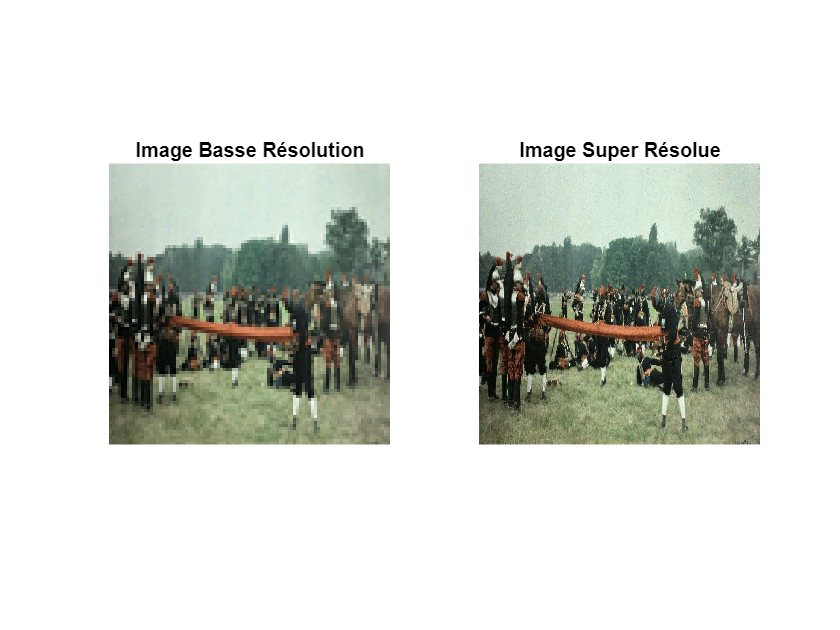

% Evaluation des résultats obtenues après entraitement
%im = imread("");
%cd ./SR
im_super_resolute = ESRGAN_2xSuperResolution(ESRGAN_2xSuperResolution(ESRGAN_2xSuperResolution(im_cropped)));

figure
subplot(1,2,1);
imshow(im_recropped);
title("Image Basse Résolution");
subplot(1,2,2);
imshow(im_super_resolute);
title("Image Super Résolue");

cd ../
imwrite(im_super_resolute, "image_sr.jpg")